# Create a Simple Baseline Test

This example shows how to create a simple test that compares test results to baseline data. Baseline tests are useful for regression testing when you change a model and want to ensure the output matches the baseline data. 

The model used in this example is `sltestBasicCruiseControlBaseline`, which has a subsystem named `Controller` with a bus of six input signals and throttle and target speed output signals. 

## Open the Model

open_system('sltestBasicCruiseControlBaseline')

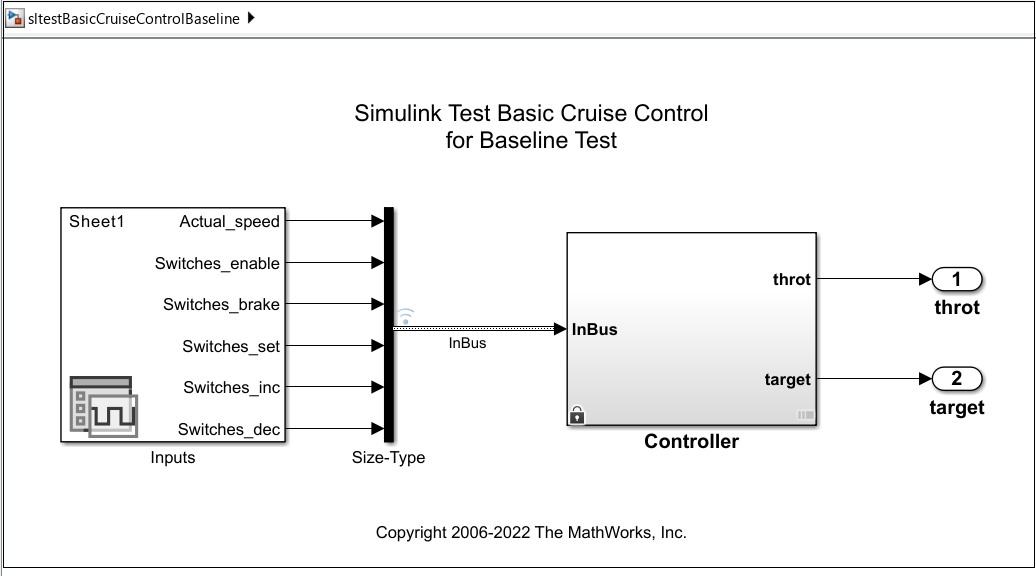

## Create the Test Harness

The test harness for this example is a separate model that you can use to test the `Controller` subsystem without changing the subsystem or main model.  

1. In the main model, right-click the `Controller` block and select **Test Harness** > **Create for 'Controller'** from the menu.

2. In the Create Test Harness dialog box, click **OK** to create the test harness using the default values. The created test harness, `sltestBasicCruiseControlBaseline_Harness1`, opens.

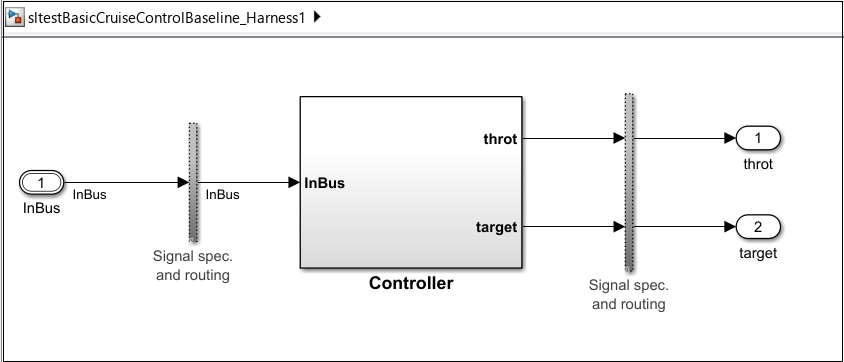

## Create the Test File and Test Structure

Open the Test Manager and create a test file and test file structure for your test. The default structure has one test suite, which has one test case. When you create the test file, it creates a new baseline test case by default. Test files can contain one or more test suites, which can contain one or more test cases. 

1. In the **Harness** tab, click **Simulink Test Manager**.

2. In the Test Manager, click **New** > **Test File** to open the Save File dialog box.

3. Enter `baseline_test` as the name of the test file and click **OK**. The test file structure opens in the **Test Browser** pane.

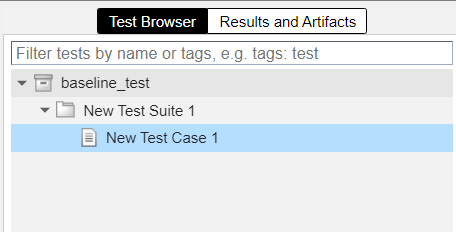

4. Right-click **New Test Case 1** and select **Rename** from the menu. Name the test case `My Baseline Test`. 

## Specify the Model and Test Harness

Set up the model and test harness to use for the test case.

1. Click **My Baseline Test** test case. 

2. In the right pane, expand the **System Under Test** section. Click the Use current model icon   next to the **Model** field to add `sltestBasicCruiseControlBaseline.slx` as the model to test.

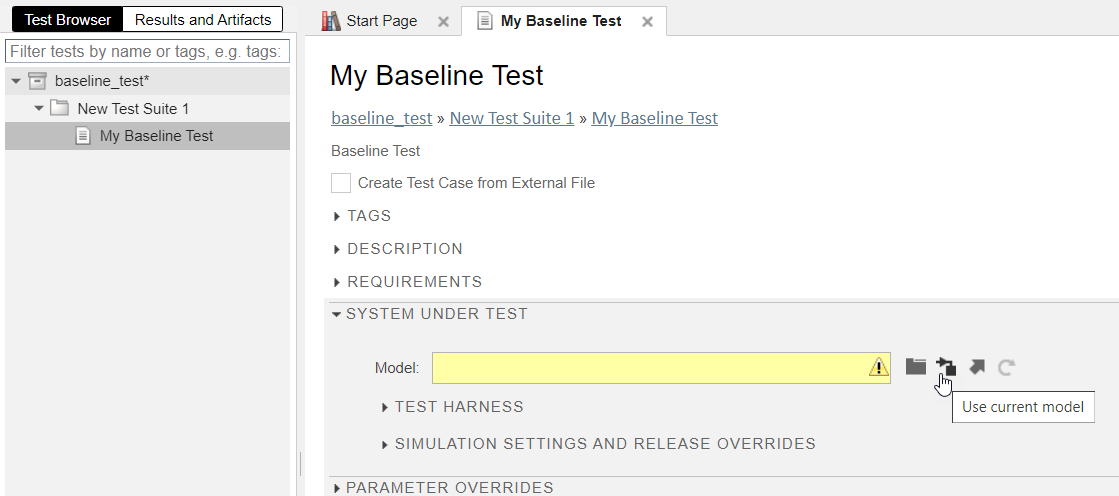

3. Expand the **Test Harness** section and click the Update model harnesses icon   next to the **Harness** drop-down menu to refresh the harness list.

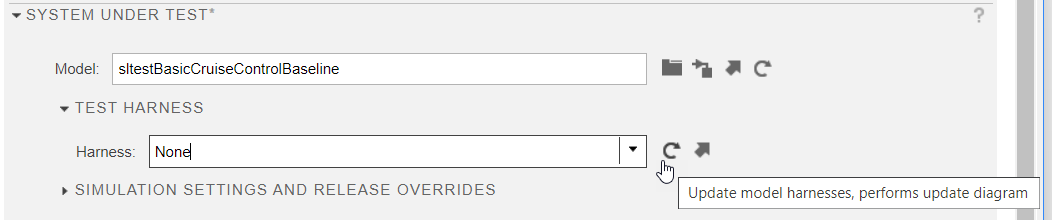

4. Select `sltestBasicCruiseControlBaseline_Harness1` from the drop-down menu.

## Specify the Inputs

This example uses the inputs provided in the `inputs.mat` file.

1. Expand the **Inputs** section.

2. Under **External Inputs**, click **Add**.

3. In the Add Input dialog box, specify or browse for the `inputs.mat` file and click **Add**.

4. The Add Input dialog box expands to show additional options. Under **Input Mapping**, leave the **Mapping Mode** property as `Block Name` and click **Map Inputs**. The Add Input dialog box updates to show that the inputs were successfully mapped.

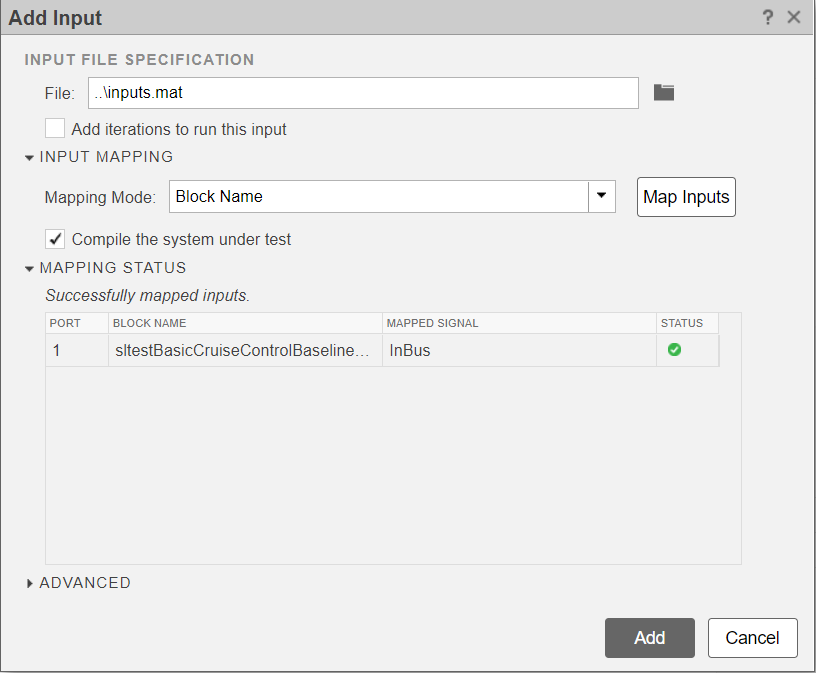

5. Click **Add** to close the dialog box and add the `inputs.mat` file to the **External Inputs** table.

## Capture the Baseline Data

Obtain and save the baseline data.

1. Expand the **Baseline Criteria** section.

2. Click **Capture** at the bottom of the section. 

3. In the Capture Baseline dialog box, enter `baseline_data` as the file name. Then, click **Capture**. The model simulates and saves the baseline data.

## Run the Test and View the Results

Run the baseline test and display the throttle signal results.

1. In the Test Browser tab, ensure the **My Baseline Test** is selected. Click **Run** in the toolstrip to run the baseline test case. 

2. When the test finishes, the Test Manager opens the **Results and Artifacts** pane. In this example, the model did not change after the baseline was captured, so the baseline test passes. 

In the Results and Artifacts pane, expand the results and select the **throt:1** signal. 

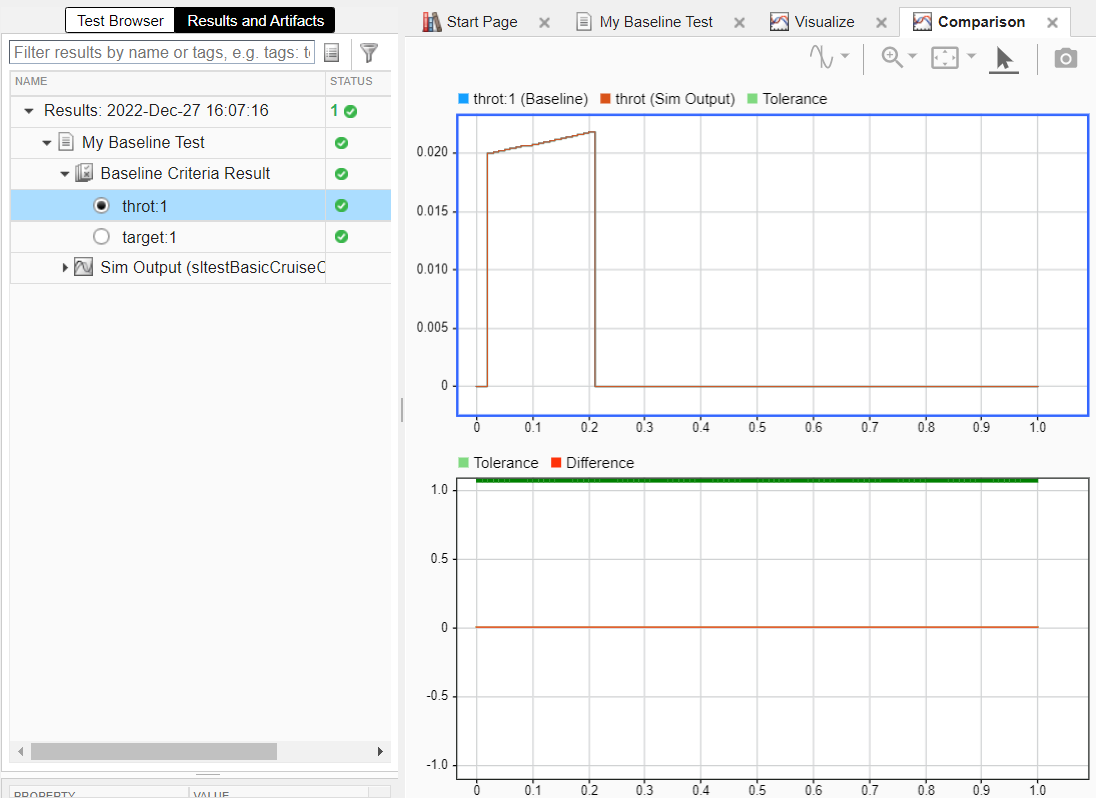

The upper plot shows both the baseline data and the simulation output data, which match. The lower plot shows that the difference between the two data sets is zero for the entire run. The test results for the **target:1** signal also match and have zero difference.

## Clean Up

Clear the test results, close the Test Manager without saving, and close the model.

sltest.testmanager.clear
sltest.testmanager.clearResults
sltest.testmanager.close
close_system('sltestBasicCruiseControlBaseline',0)

*Copyright 2022 The MathWorks, Inc.*